## TOPIC 19: Revisiting images and graphics

ENGR105, 11/5/20

#### Reminder: audio processing

- ***Audio signal***: this is simply an `Nx2` array of type **double**. In MATLAB, each entry in the audio signal must fall in the interval `[-1,1]`. We can import audio using `audioread` and playback using `sound`.

- ***Sampling frequency****:* The number of points per second used to discretize a continous signal. 

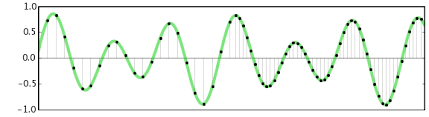

*            Source: Audacity*

- ***Remember***: audio data is just an array of decimal values. This can be manipulated using all of our previous array operations.

#### Reminder: image processing

An image **may be read into MATLAB** using the `imread` function.

% Read the first image
image1 = imread('L19_image1color.jpg');

An image may be displayed using `imshow`:

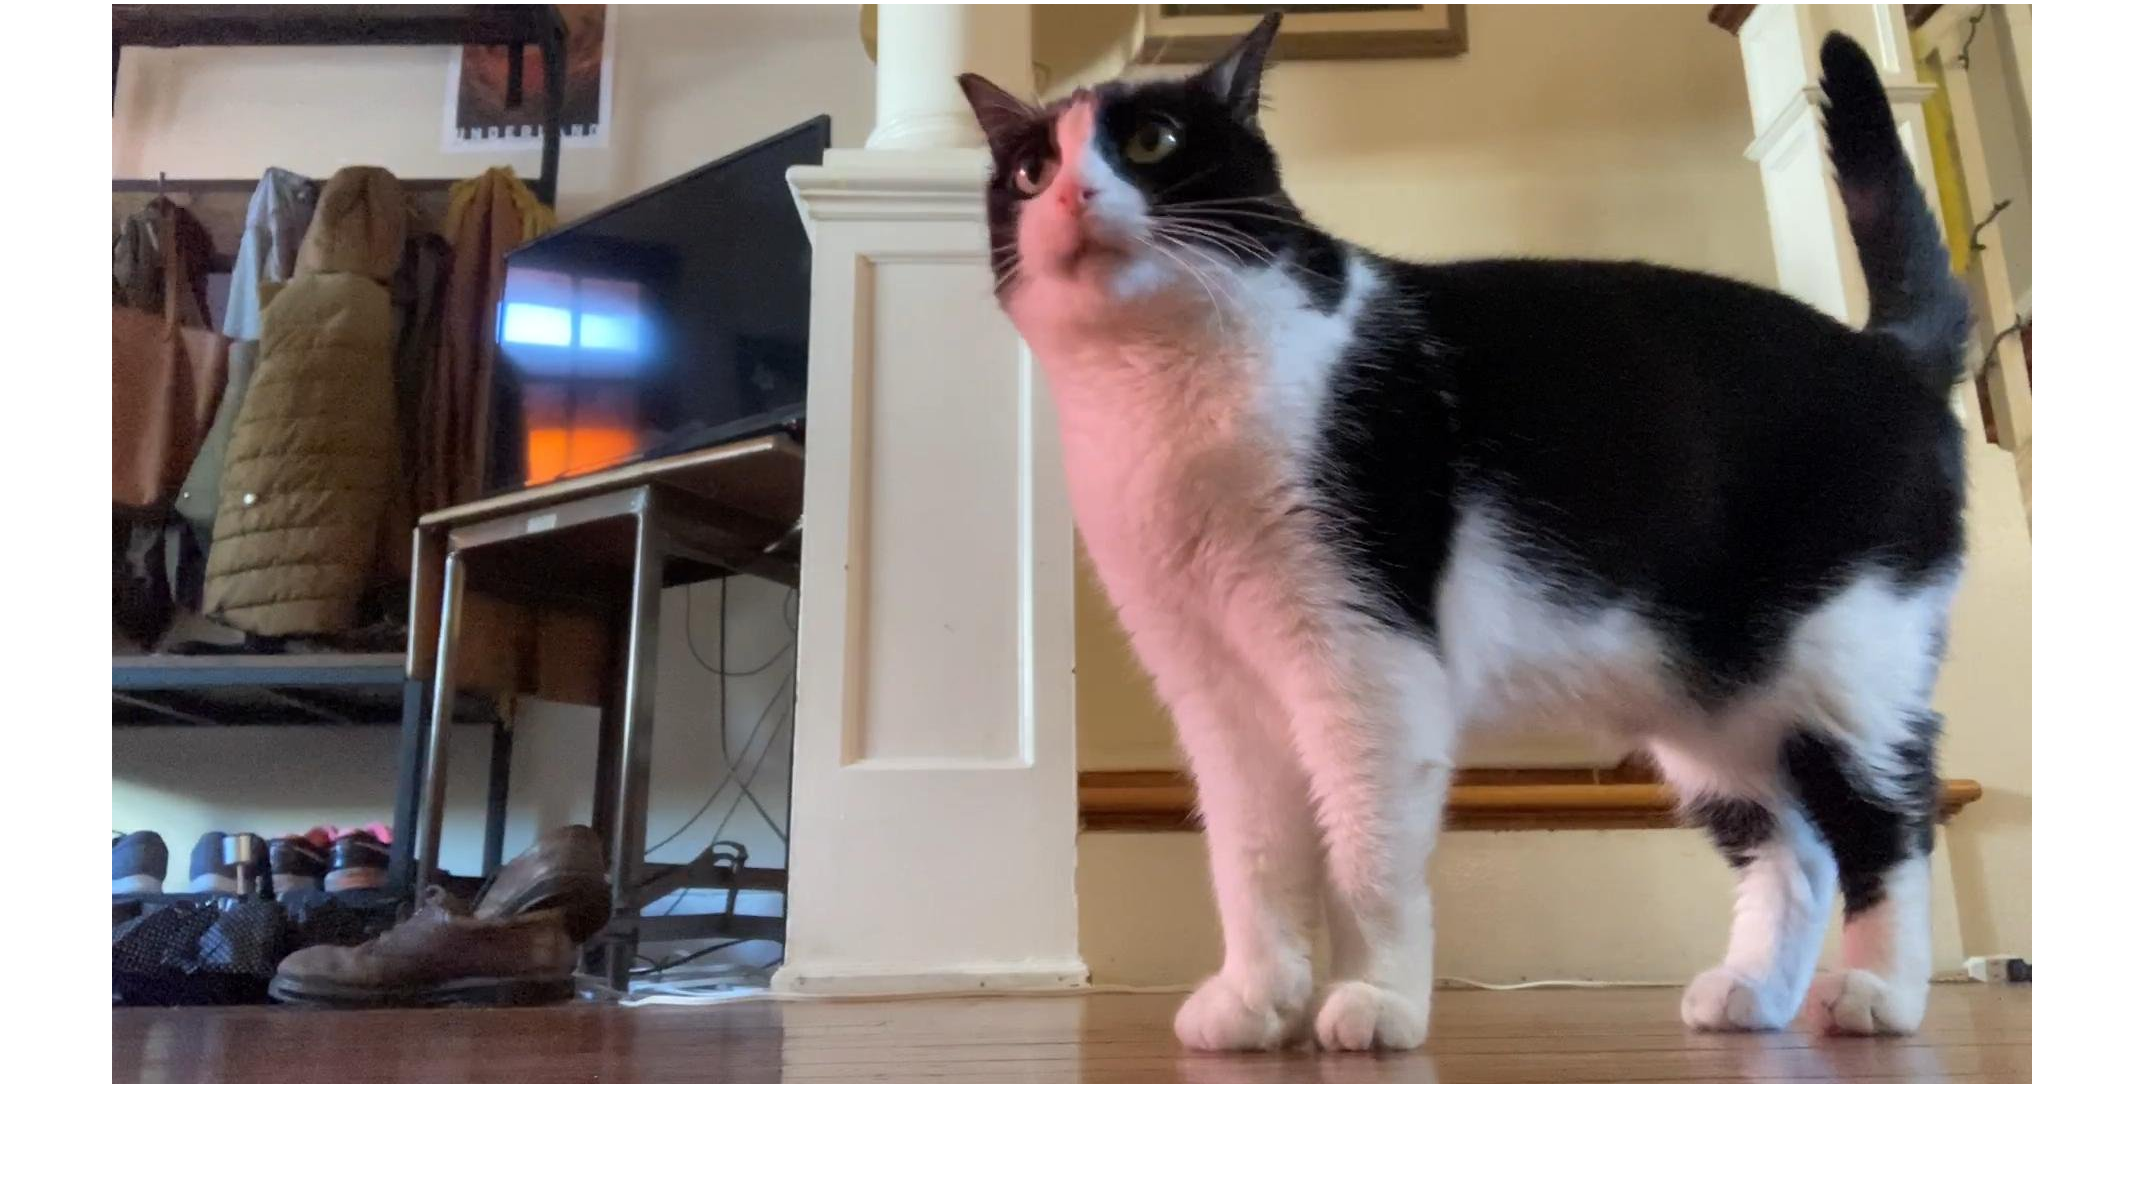

imshow(image1)

**Images are just "integer matrices," ** in which the each index corresponds to a unique **pixel**, and the value of the corresponding element is the **gray value** of that pixel. The bit depth of an image corresponds to the range of possible integer values each element can take.

% Bit depth of image
class(image1)

ans = 'uint8'

Images can be **cropped** using **array indexing**.

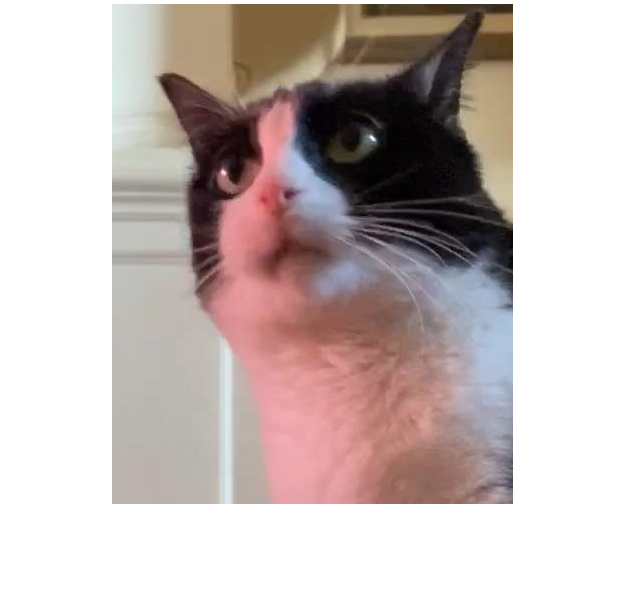

% Create a cropped image: note the array indices
imX = image1(1:500,800:1200,:);   
imshow(imX)

**Grayscale images** have one value associated with each **X-Y index position**, whereas color images have three values (R-G-B). As a result, color images have **three dimensions**.

% Dimensions of image1
size(imX)

ans =    500   401     3


Since the "third dimension" corresponds to the **color**, each "channel" (*red, green, or blue*) can be displayed by setting the other channels to zero.

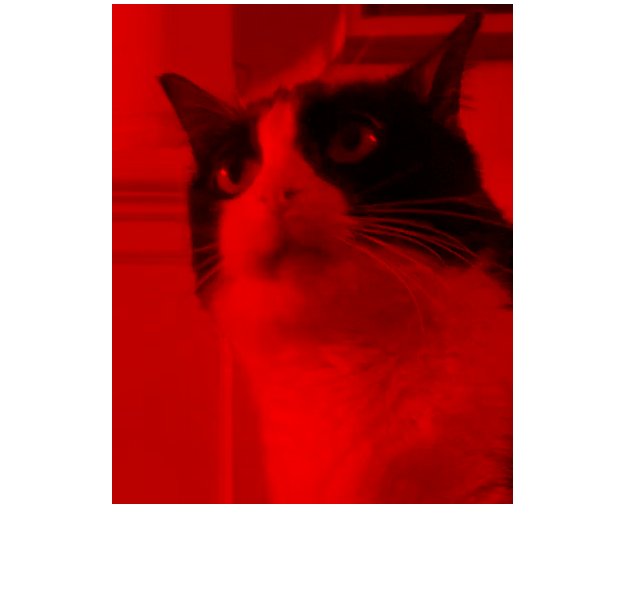

% Display red channel
imX_red = imX;
imX_red(:,:,2:3) = 0;
imshow(imX_red)

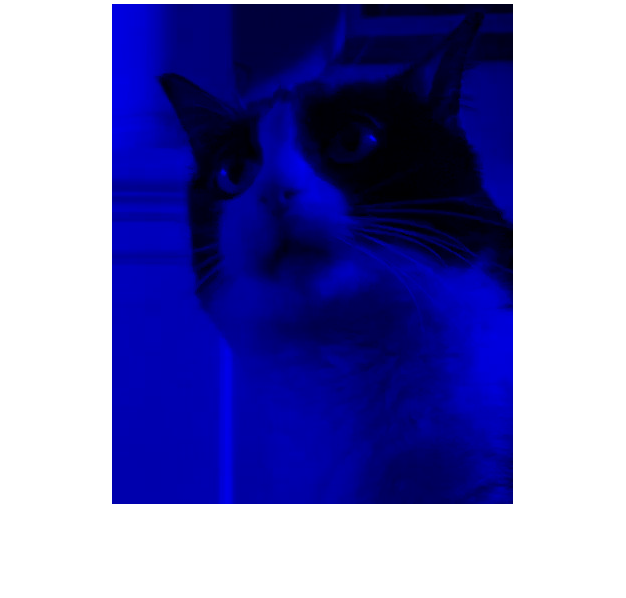

% Display blue channel
imX_blue = imX;
imX_blue(:,:,1:2) = 0;
imshow(imX_blue)

Displaying one color channel as a grayscale image

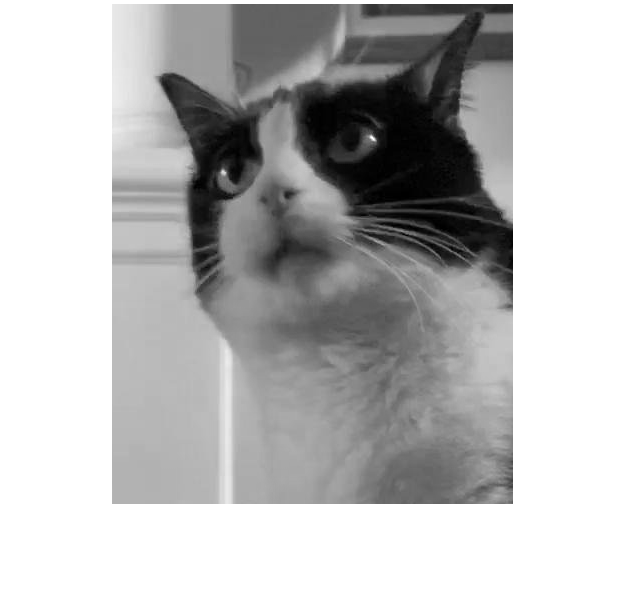

% Create grayscale image from green channel
imX_gray = imX(:, :, 2);
imshow(imX_gray)

By changing the pixel value of image elements, you can change the image that will be displayed.

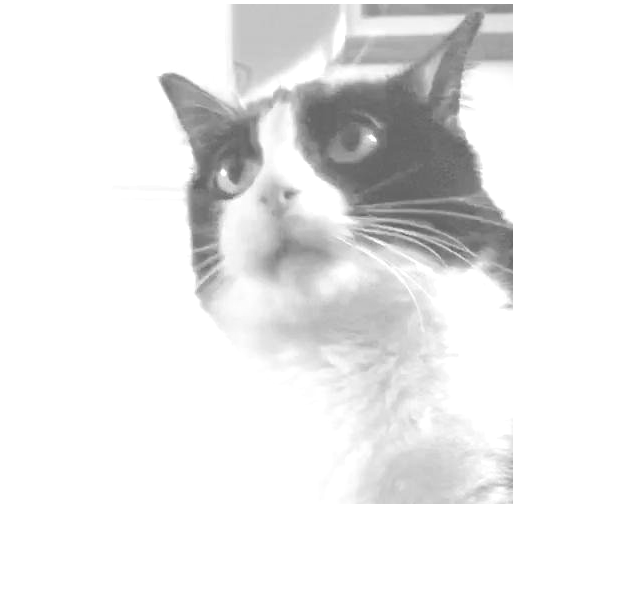

% Change the "brightness" of a given pixel
imshow(imX_gray + 100)

You can use **logical indexing** on a given image to obtain or modify specific pixel values.

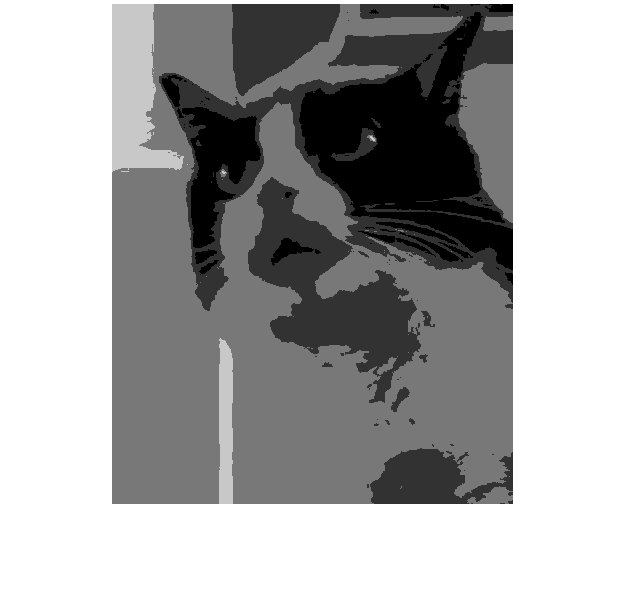

% Preallocate array to store information about image to be produced
imX2 = uint8(zeros(size(imX_gray)));

% Loop through some values to convert the image into "buckets" 
% of only a few gray values   
gvThresh = [0,50,120,200,255];
for k = 1:length(gvThresh)-1
    % All pixel between corresponding gray value limits are set to the
    % lower limit
    imX2(imX_gray > gvThresh(k) & imX_gray <= gvThresh(k+1)) = gvThresh(k);
end
% Display image
imshow(imX2)

**Note**: the above example uses a `for` loop -- don't forget about vectorization

#### Basic image filtering

Last time, we used `filter` to apply a **rolling mean filter** to a temporal, 1-D signal:

            
$$y\left(n\right)=\frac{1}{\textrm{windowSize}}\left(x\left(n\right)+x\left(n-1\right)+\ldotp \ldotp \ldotp +x\left(n-\textrm{windowSize}+1\right)\right)$$


- $y\left(n\right)$: the filtered output at point $x=n$

- $x\left(n\right)$: the raw, unfilterd signal at $x=n$.

The result was us being able to remove high frequency noise to effectively smoothe the signal.

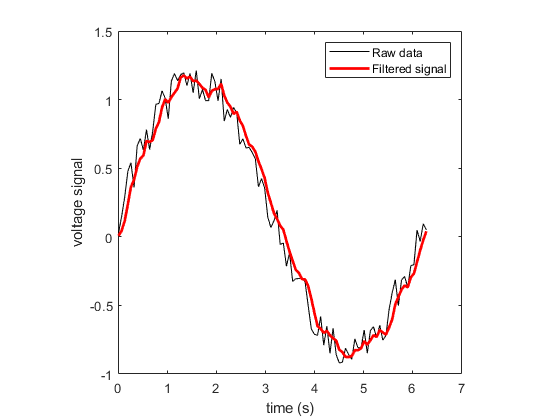

One can apply a similar concept to images: we can use `filter2` to create a "*2-D mean filter*" to remove "high frequency" details. As a result, the filter image will appear "**blurry**."  A few notes:

- This filtering is the result of **2D convolution** of the **image** with a **kernel**.

- This **2-D kernel is equivalent to the 1-D "window"** in the example above. For *every pixel location*, it will take the average of all nearby pixel values.

- Note that the kernal is **typically** **normalized by the sum of all elements.**

% Create the kernel
B = ones(10);
B = B/sum(B,'all');


% Filter image using filter2
imX_filt = filter2(B, imX_gray)

imX_filt =    83.1000   96.8400  110.5800  124.3200  138.0000  137.7000  137.4600  137.1600  136.9200  136.6200  136.2600  135.9600  135.7200  135.4800  135.2400  134.9400  134.5800  134.2800  133.9200  133.6200  133.2600  132.9000  132.4200  131.9400  131.4000  130.8600  130.3800  129.9000  129.4200  128.9400  128.4600  127.8600  127.1400  126.3600  125.6400  124.9800  124.2600  123.4200  122.5200  121.5600  120.6600  119.7600  118.8600  117.8400  116.6400  115.4400  114.1800  112.8600  111.3600  109.7400
   96.9500  112.9800  129.0100  145.0400  161.0000  160.6500  160.3700  160.0200  159.7400  159.3900  158.9700  158.6200  158.3400  158.0600  157.7800  157.4300  157.0100  156.6600  156.2400  155.8900  155.4700  155.0500  154.4900  153.9300  153.3000  152.6700  152.1100  151.5500  150.9900  150.4300  149.8700  149.1700  148.3300  147.4200  146.5800  145.8100  144.9700  143.9900  142.9400  141.8200  140.7700  139.7200  138.6700  137.4800  136.0800  134.6800  133.2100  131.6700  129.92

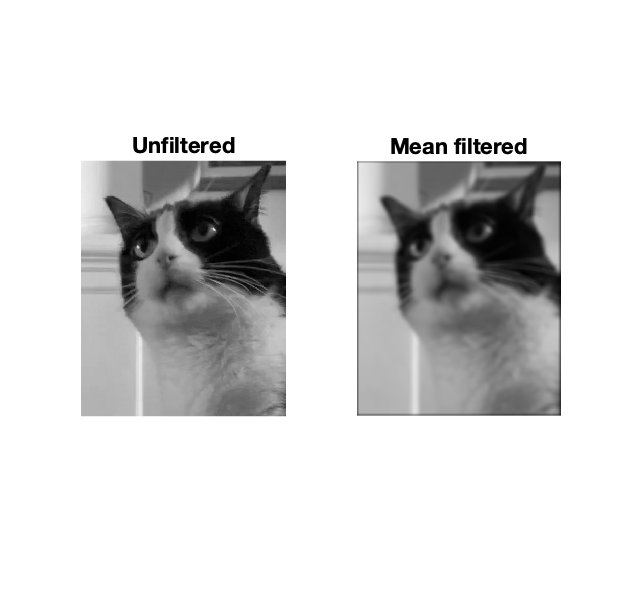

% Convert filtered image to 8-bit
% NOTE: images must be 8-bit integer values
imX_filt = uint8(imX_filt);

% Create a subplot showing both images
% First image: unfiltered
subplot(1,2,1)
imshow(imX_gray)
title('Unfiltered')
% Second image: mean filtered
subplot(1,2,2)
imshow(imX_filt)
title('Mean filtered')

**Note**: the above is a simple kernel for mean filtering an image. Other kernels exist for edge detection, image sharpening, and applying a Gaussian blur.

#### Binary (logical) images

Converting an image to a **logical array** is known as creating a **binary image** (or black/white image or logical image).

% Close all previous images
close all
% Create a binary image from imX2
imX_bw = imX_filt<50;
% Depict properties of the black/white image
whos imX_bw

  Name          Size              Bytes  Class      Attributes

  imX_bw      500x401            200500  logical              



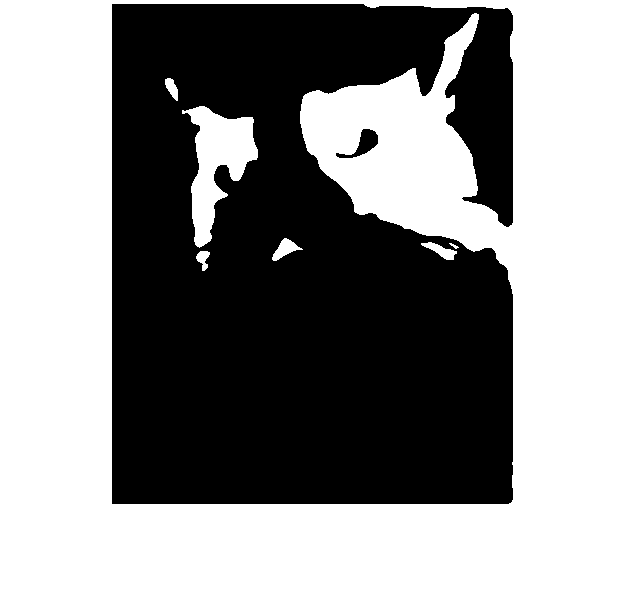

% Display image
imshow(imX_bw)

**Binary images** are useful for extracting and analyzing "objects" in an image. The following are two useful functions

- `bwlabel` -- labels (isolates) the different connected components of a binary image.

- `imfill` -- perform flood fill operation, convert dark (0) pixels to white (1). The most common setting I use is to fill `'holes' --` i.e. fill in dark (0) pixels that are internally present within a white (1) object.

- `regionprops` -- gives quantiative information about a binary "object" in an image.

**Example**. Let's apply all of these functions to the above black/white image

% 1) Label all (1) objects in binary image
[L, num] = bwlabel(imX_bw);

% The number of unique binary objects
num

num = 12

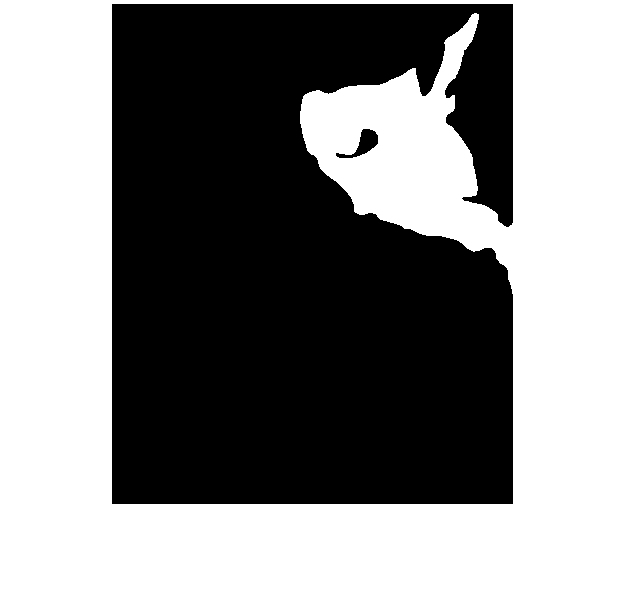

% Inspect different binary objects
imshow(L == 5)

% 2) Fill in dark (0) pixels INSIDE object
% Store specific binary image as a variable
im = L == 5;
im2 = imfill(im,'holes')

im2 = 500×401 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

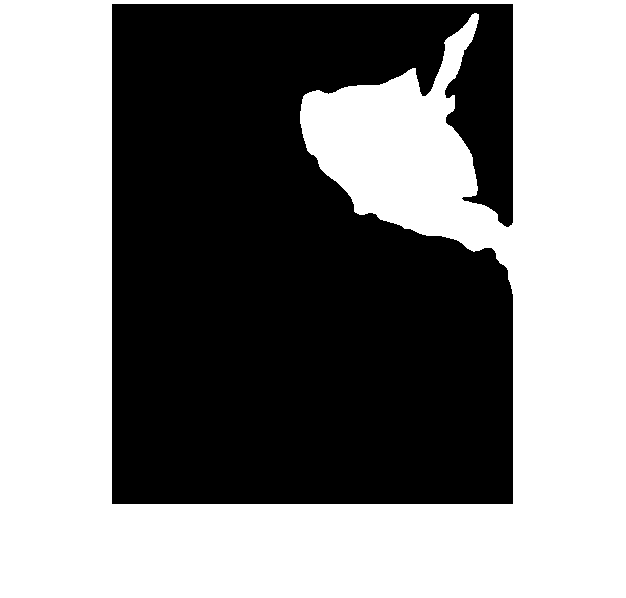

imshow(im2)

% Use regionprops to obtain information from the isolated object
pic_info = regionprops(im2, 'all')

pic_info = struct with fields:
                   Area: 23651
               Centroid: [294.7183 151.5875]
            BoundingBox: [188.5000 9.5000 213 281]
            SubarrayIdx: {[1×281 double]  [1×213 double]}
        MajorAxisLength: 234.9789
        MinorAxisLength: 166.7343
           Eccentricity: 0.7046
            Orientation: -46.0300
             ConvexHull: [110×2 double]
            ConvexImage: [281×213 logical]
             ConvexArea: 36063
            Circularity: 0.3221
                  Image: [281×213 logical]
            FilledImage: [281×213 logical]
             FilledArea: 23651
            EulerNumber: 1
                Extrema: [8×2 double]
          EquivDiameter: 173.5321
               Solidity: 0.6558
                 Extent: 0.3952
           PixelIdxList: [23651×1 double]
              PixelList: [23651×2 double]
              Perimeter: 960.5990
           PerimeterOld: 1.0112e+03
       MaxFeretDiameter: 288.6243
          MaxFeretAngle: -136.6847
 

**Note**: `pic_info` is a **structure array**, where each field can be accessed using dot notation, as before.

% Area in pixels of binary object
a = pic_info.Area

a = 23651

% How "circular" the object is
b = pic_info.Circularity

b = 0.3221

### Revisiting plotting and graphics

A few **useful functions** for creating and adding graphics:

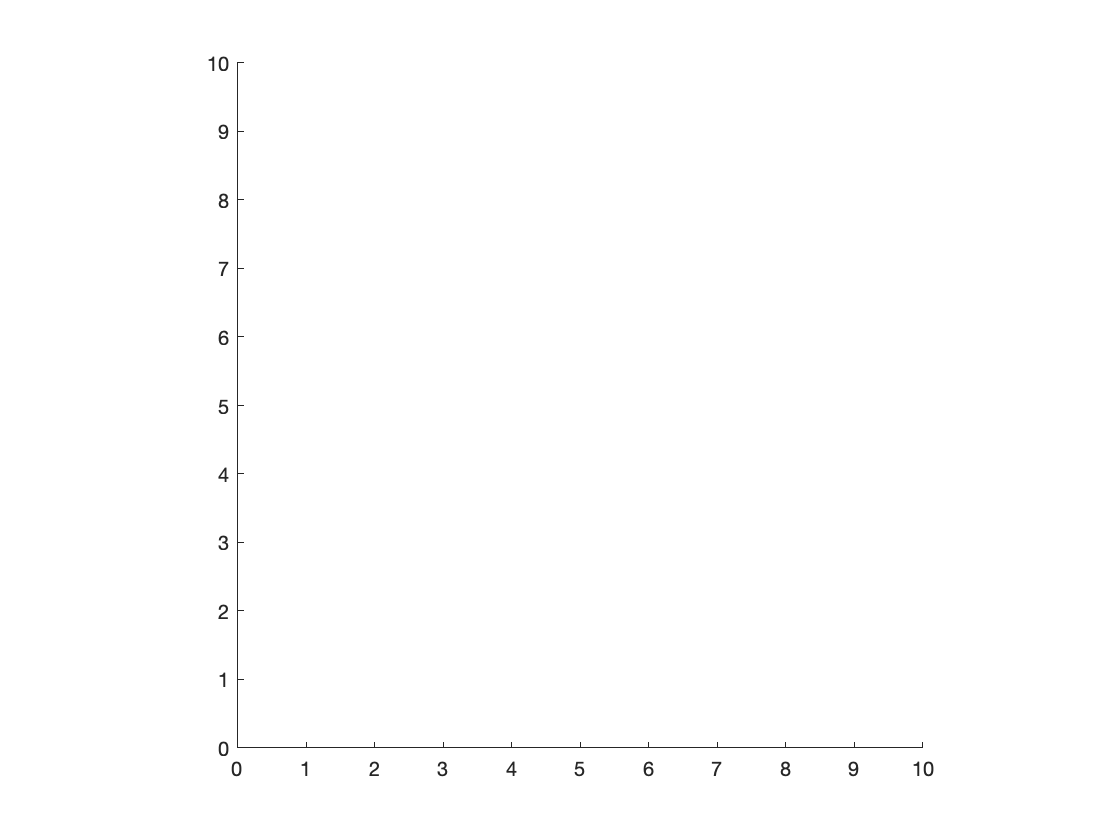

% First, create a blank set of axes to add to
close all
axes;
xlim([0,10]);
ylim([0,10]);
axis square

- `rectangle` -- adds a rectangle, rounded-rectangle, or ellipse

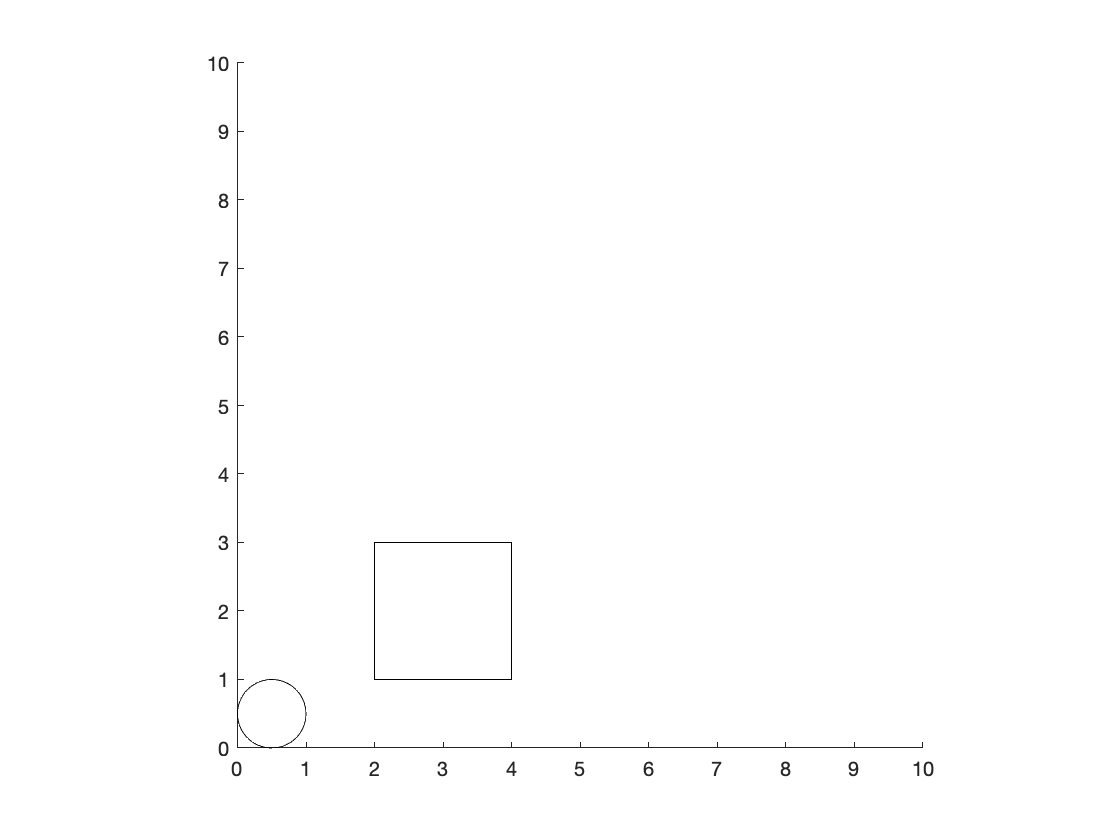

% Add two rectangles
h1 = rectangle('Position',[2,1,2,2]);
h2 = rectangle('Position',[0,0,1,1],'Curvature',[1,1]);

As before, graphics object parameters can be changed and accessed by referencing the **graphics object handle**.

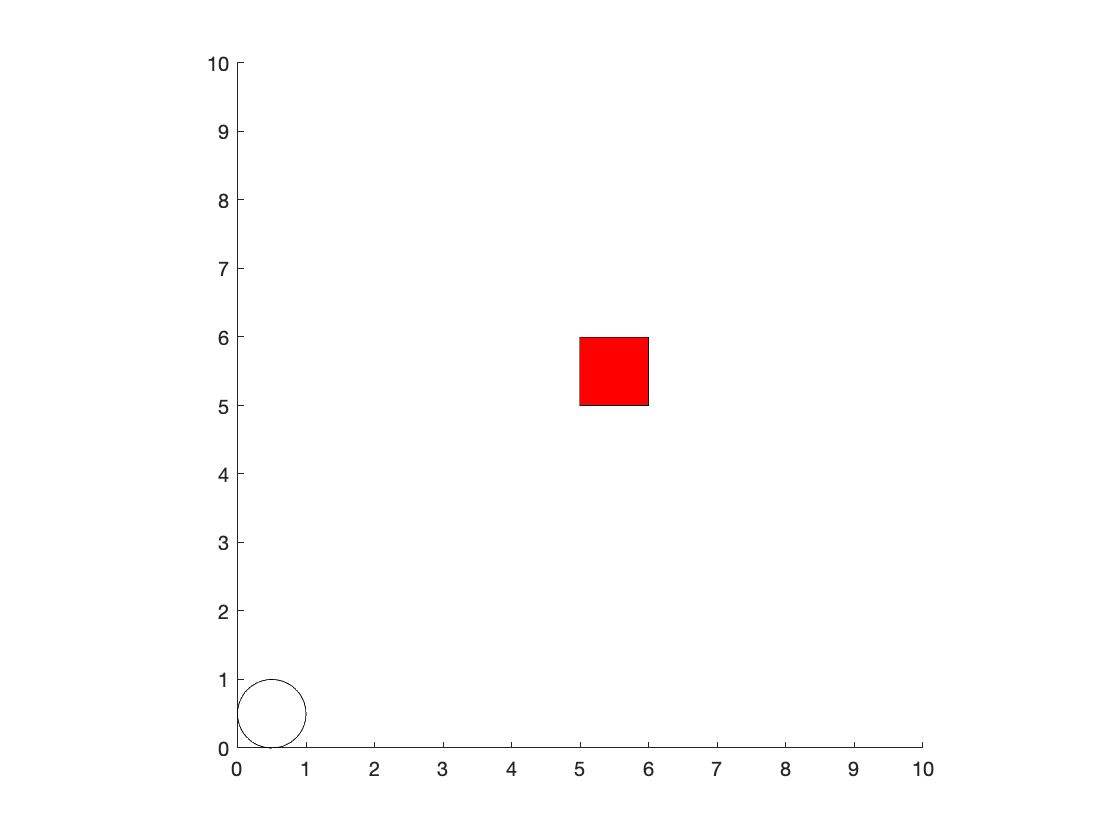

h1.FaceColor = 'r';
h1.Position = [5,5,1,1];

- `text` -- adds text to a plot at the defined position

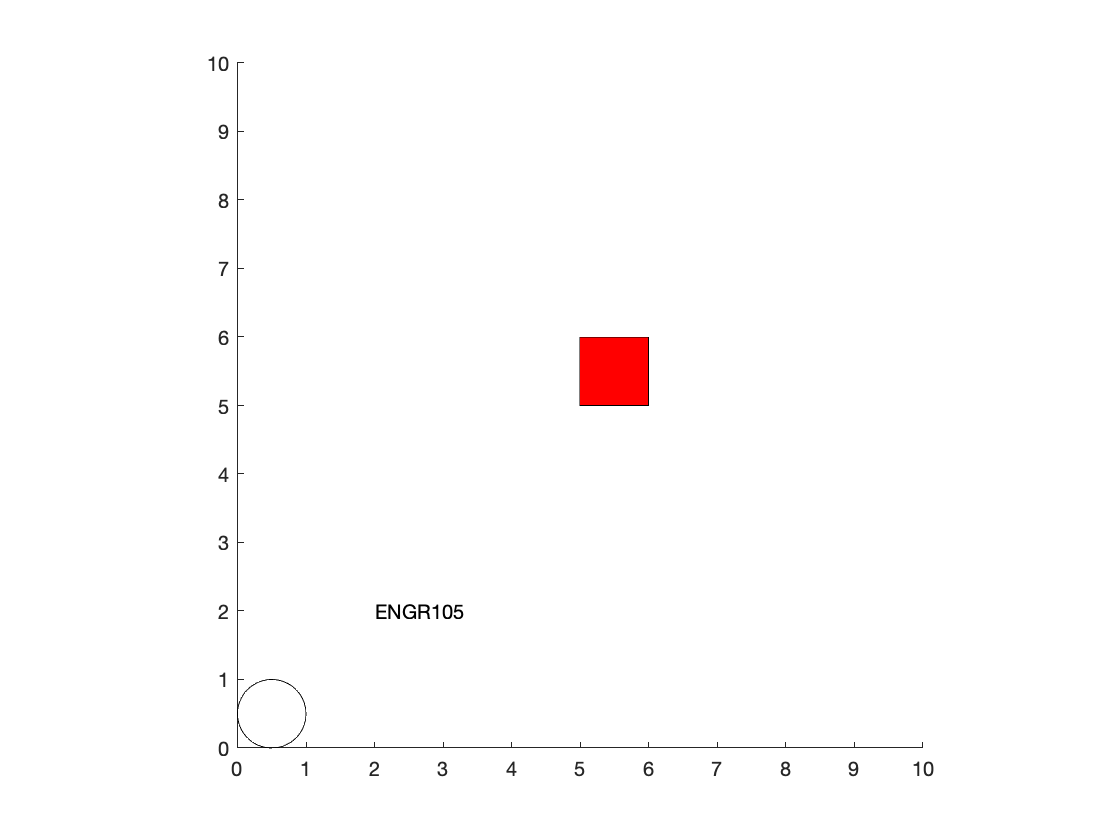

text(2,2,'ENGR105')

#### Animating objects

In lecture 18, we **imported positional data** for creating a visualization of particle motion.

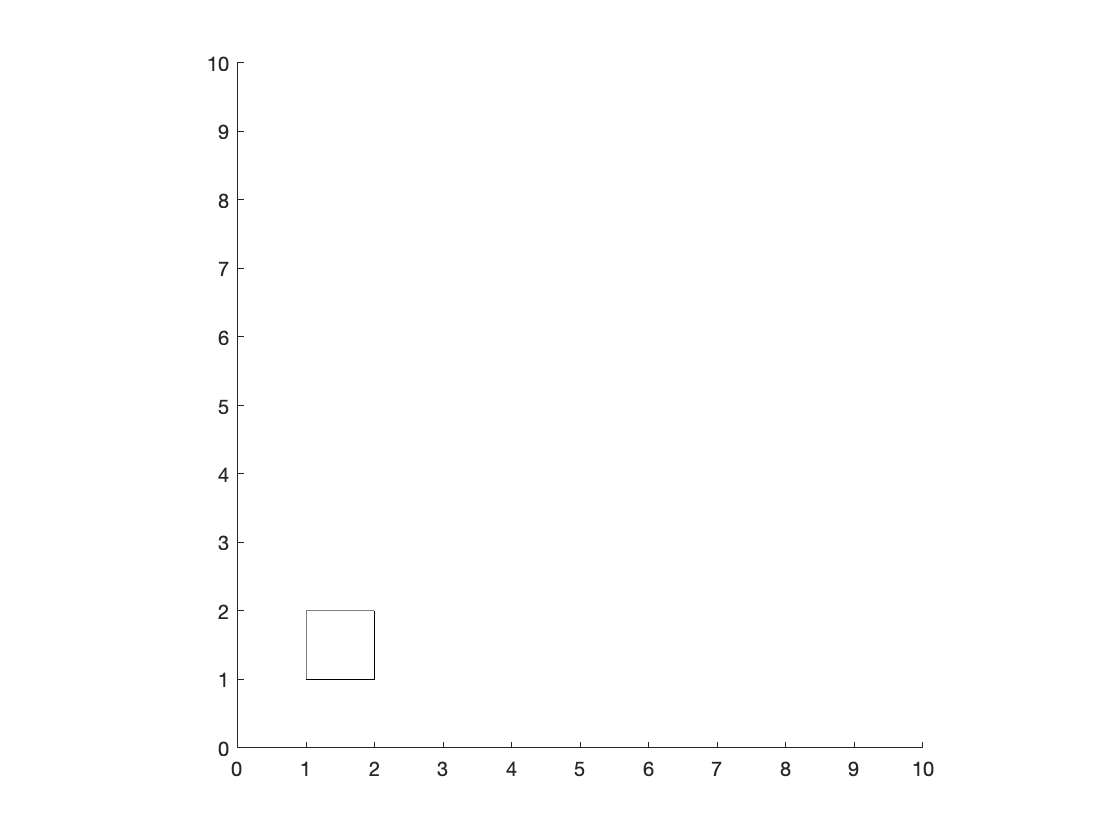

figure
axis square
xlim([0,10])
ylim([0,10])
h3 = rectangle('Position',[1,1,1,1]);

One could also specify positions based on a **mathematical expression.**

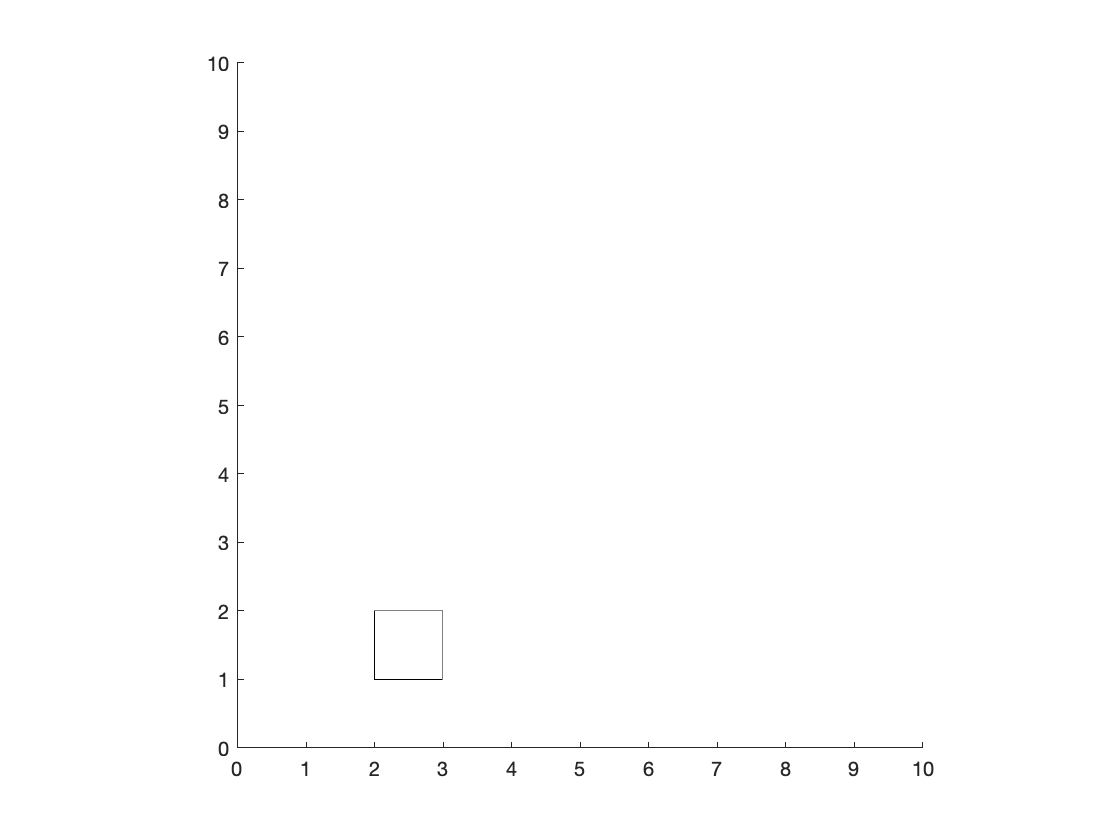

% Create time and positional vectors
t = 1:10;
x = cos(t/10*2*pi)+1;
y = sin(t/10*2*pi)+1;

% For each time point specified above, move the rectangle to a new spot
for k = t
    % Pause MATLAB for 0.5 seconds
    pause(0.5)
    % Update to new position
    h3.Position = [x(k),y(k),1,1];
end

**Note**: `pause(t)` pauses for `t` seconds

**Example.** Plot (in 3D) $x\left(t\right)=\sin \left(t\right)$ , $y\left(t\right)=\cos \left(t\right)$  ,  $z\left(t\right)=\cos \left(t\right)$ for $t=\left\lbrack 0,2\pi \right\rbrack$

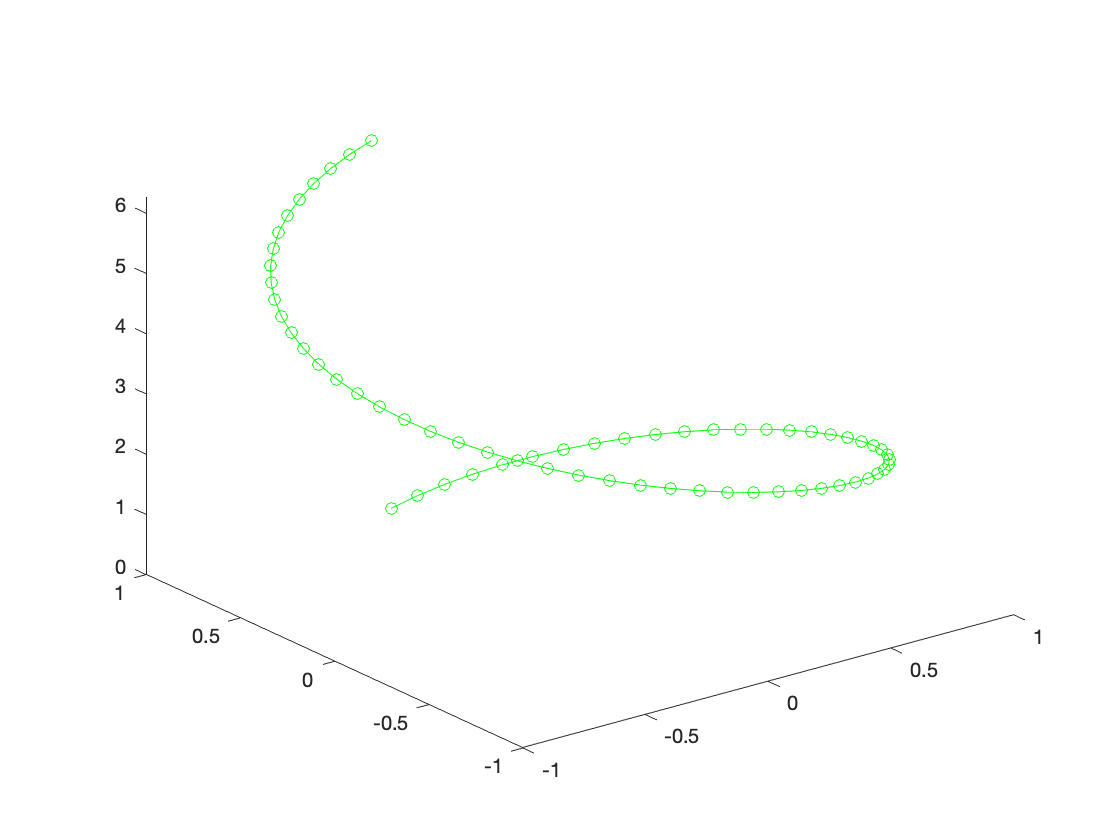

% New plot
figure;

% Step 1: create vectors for time and corresponding positions
t = 0:.1:2*pi;
x = sin(t); 
y = cos(t); 
z = t;
 
% Step 2: Plot nothing and establish axis bounds.
p = plot3(NaN,NaN,NaN,'go-');
xlim([-1,1])
ylim([-1,1])
zlim([0,2*pi])

% Step 3: the plot over time
for jj = 1:length(x)
    p.XData = x(1:jj);
    p.YData = y(1:jj);
    p.ZData = z(1:jj);
    pause(.1)   % Pause for 100 ms
end

#### Keyboard callbacks

Keyboard interactions with a script or interface often make for a more useful and interactive experience. Such interfaces may include movement of on-screen objects by keyboard direction, selection points or regions on a pair of axes, or selecting options or menu items. Interaction between the keyboard and your user interface/program are achieved using keyboard callbacks. 

*Additional resources:*

- [MathWorks documentation](https://www.mathworks.com/help/matlab/creating_plots/callbacks-programmed-response-to-user-action.html)

- [Callback definitions](https://www.mathworks.com/help/matlab/creating_plots/callback-definition.html)

The general format for adding a **keyboard callback** to a figure is as follows. The `'KeyPressFcn'` field is just a parameter associated with a figure graphics handle.

*The corresponding callback function stored at the end of the document:*

**Notes:**

- **Keyboard callbacks are often associated with a **`figure`**. **

- `hObj` refers to the calling object but is unnecessary in most cases, *i*.*e*. `hObj` could be listed as `~ `in most situations.

- `eventdata` contains several fields, one of which is the keyboard key pressed

**Useful**: to view the character codes or names associated with a keystroke, type the following into the command line:

**Example 1.** Printing to command line by pressing the `'w'` key.

close all % Close all previous figures
% Figure to be associated with callback
h1 = figure;
set(h1,'Visible','on')
% Specify the function that will be executed upon a key press event


**Note**: since the call back is associated with a figure, when using a LiveScript file, the visibility of the figure needs to be set to `'on'`

**Example 2.** Moving a ball

In the following, example, we can use the `arrow keys` to move a ball across the screen, while `'q'` closes the figure window. The following callback function is located at the end of the LiveScript document.

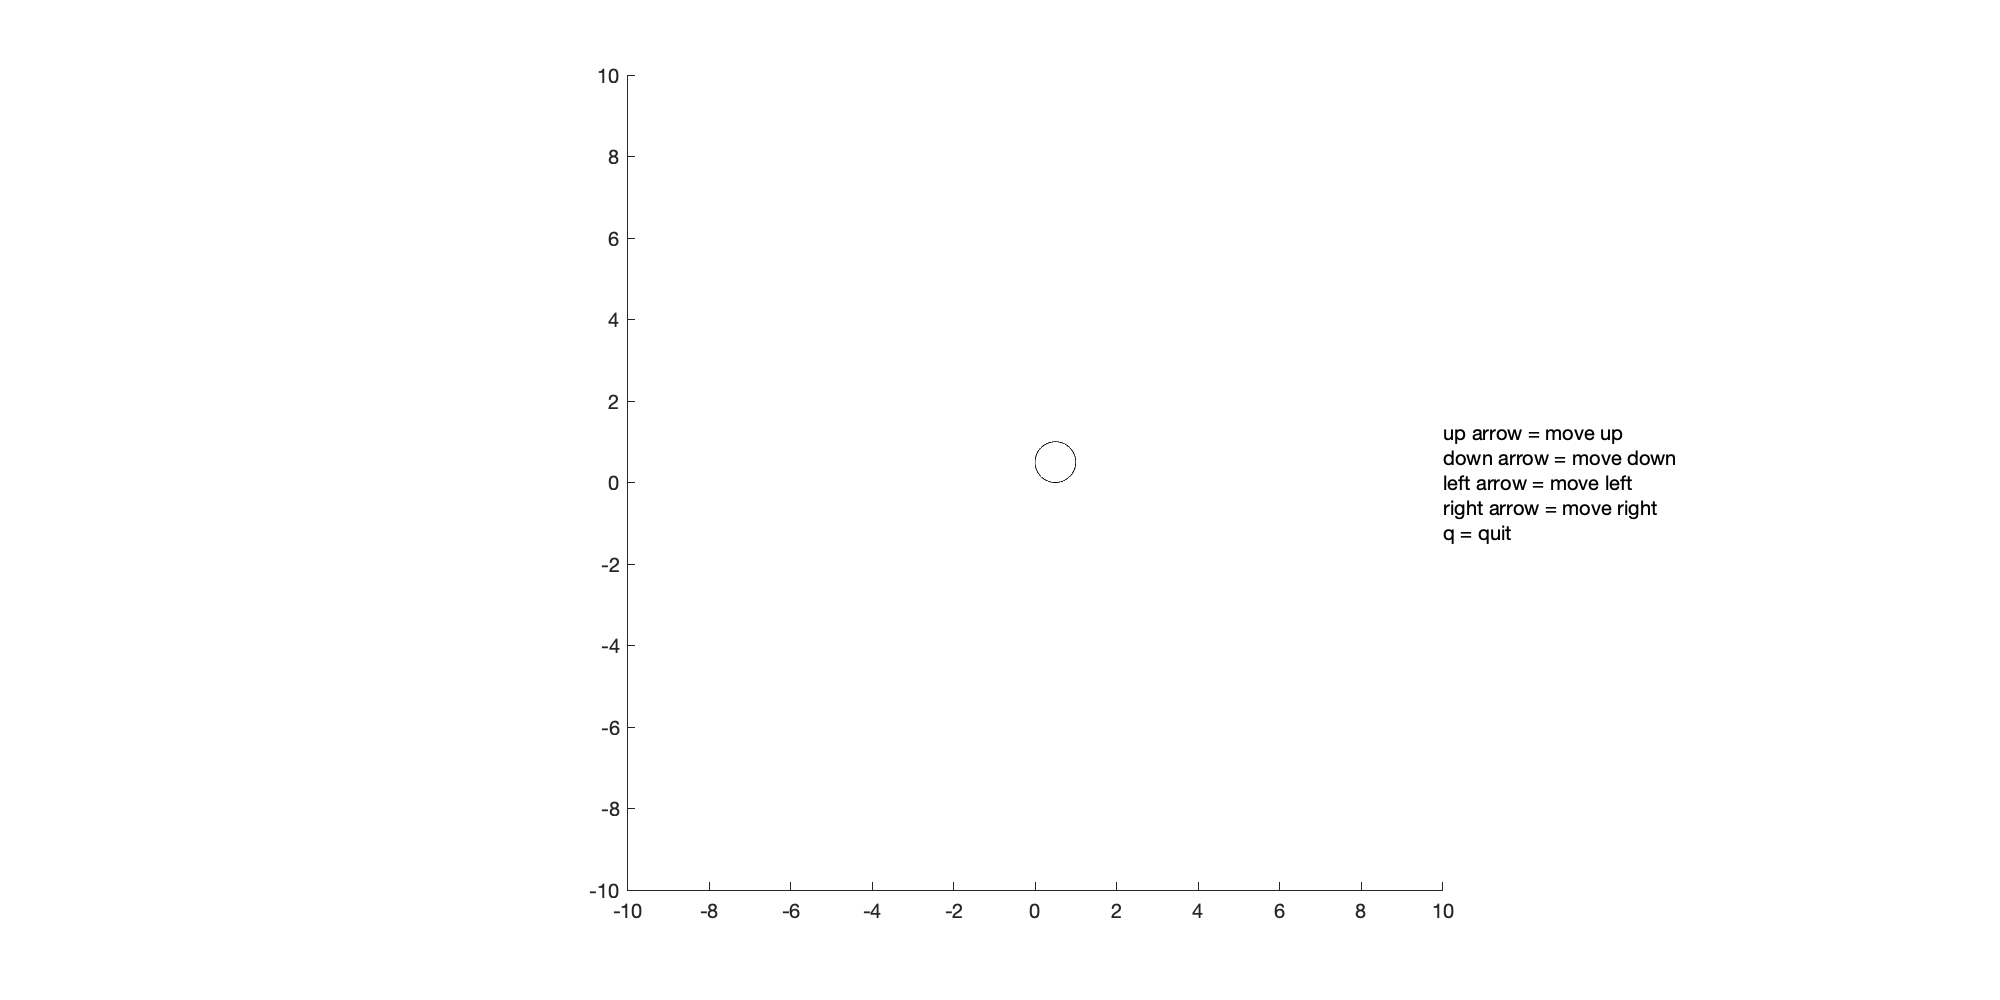

% Initialize the figure and assign the keyboard callback
% function.
hFig = figure('Position',[200,200,1000,500]);

% Specify plot formatting
text(10,0,{'up arrow = move up','down arrow = move down', ...
    'left arrow = move left','right arrow = move right','q = quit'})
axis square
xlim([-10,10])
ylim([-10,10])

% Create a "ball" and place it at [0,0] initially
hBall = rectangle('Position',[0,0,1,1],'Curvature',[1,1]);

% Assign a keyboard call back
hFig.KeyPressFcn = {@DoWhenKeyIsPressed,hBall};

% Set figure to visible -> have it pop out so we can input the keyboard
% call backs
set(hFig,'Visible','on')

## Functions for this Lecture

- Introductory callback example

function FctnToCall(~,eventdata)
    if strcmp(eventdata.Key,'w')
        disp('Pressed a w!')
    end
end


- Moving ball example

function DoWhenKeyIsPressed(~,eventdata,hBall)
    % Utilizes keypresses to move the x/y coordinates of the
    % ball or closes the figure.
    
    % Movement increment
    inc = 0.3; 

    % Move up
    if strcmp(eventdata.Key,'uparrow')
        hBall.Position(2) = hBall.Position(2)+inc;
    % Move down
    elseif strcmp(eventdata.Key,'downarrow')
        hBall.Position(2) = hBall.Position(2)-inc;
    % Move left
    elseif strcmp(eventdata.Key,'leftarrow') 
        hBall.Position(1) = hBall.Position(1)-inc;
    % Move right
    elseif strcmp(eventdata.Key,'rightarrow')   
        hBall.Position(1) = hBall.Position(1)+inc;
    % Close figure
    elseif strcmp(eventdata.Key,'q')  
        close()
    % Display invalid keystroke
    else
        disp('Key not mapped')
    end
end